format shortg
clear all

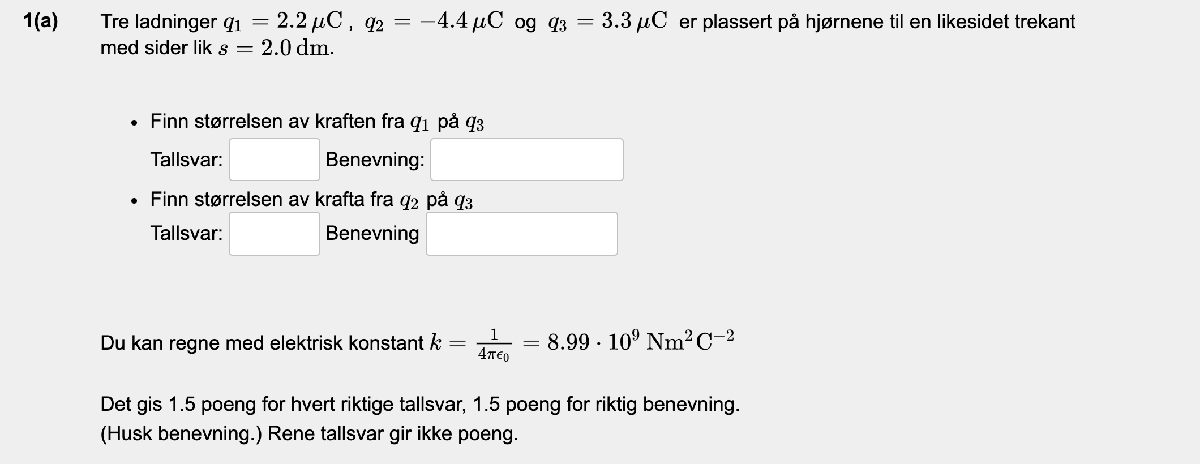

q1 = 2.2 * 10^-6;
q2 = -4.4 * 10^-6;
q3 = 3.3 * 10^-6;
s = 2.0 * 10^-1;

F_13 = KraftMellomPunktladninger(0, q1, q3, s);
signif(F_13, 2) % Newton

ans =           1.6


F_23 = KraftMellomPunktladninger(0, q2, q3, s);
signif(F_23, 2) % Newton

ans =           3.3


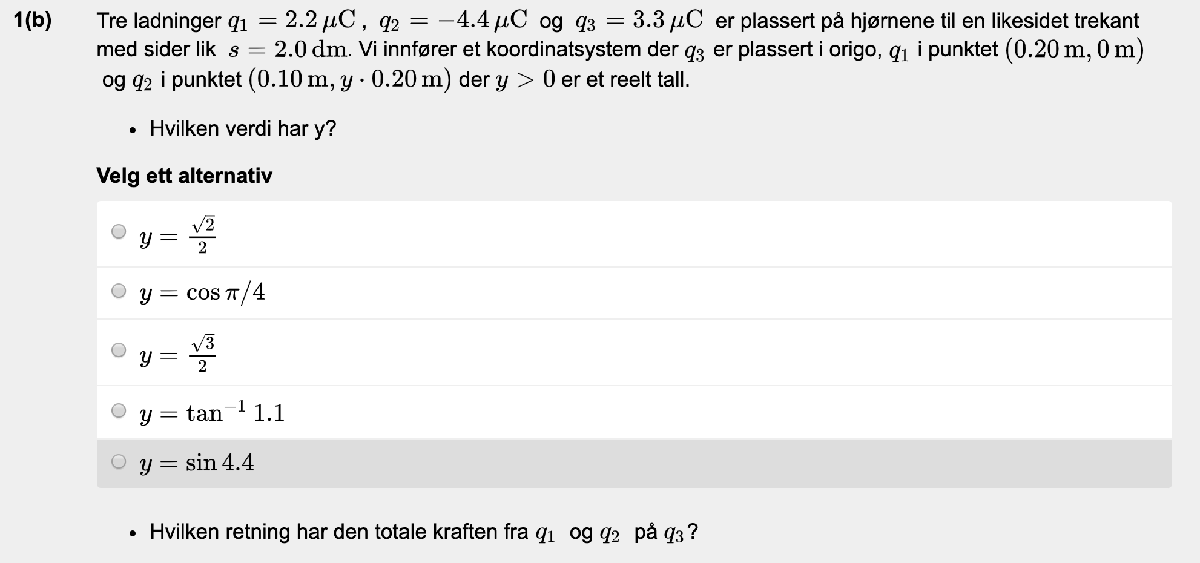

d = asind(0.1/0.2)

d =            30



$$\cos \left(d\right)=\frac{\left(y*0\ldotp 2\right)}{0\ldotp 2}$$


y = cosd(d) % sqrt(3)/2

y =       0.86603


sqrt(3)/2

ans =       0.86603


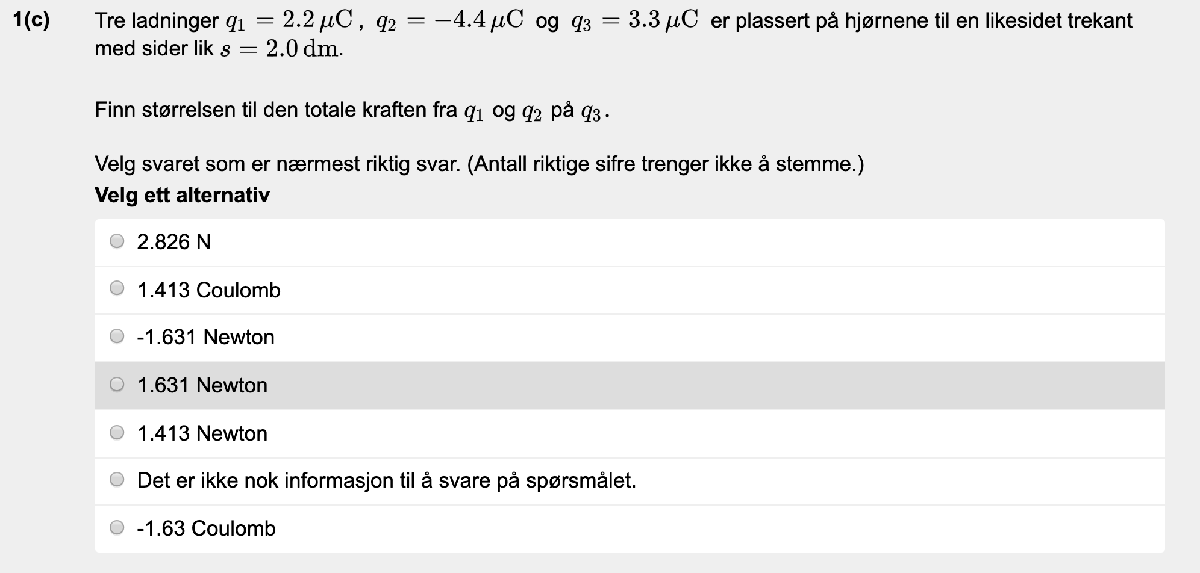

Vi har funnet lengden av kraften fra 2 på 3, siden kraften fra q1 kansellere det horisontale fra q2 er neste kraften som virker på q3 ven vertikale kraften fra q2:

F_23 * cosd(30)

ans =        2.8262


fprintf('Kraft fra q1 på q3: %g\nKraft fra q2 på q3: %g', F_13, F_23)

Kraft fra q1 på q3: 1.63168
Kraft fra q2 på q3: 3.26337

kraft_fra_q1 = F_23 * [1/2 sqrt(3)/2]

kraft_fra_q1 =        1.6317       2.8262


kraft_fra_q2 = F_13 * [-1 0]

kraft_fra_q2 =       -1.6317            0


sum_q1_og_q2 = kraft_fra_q1 + kraft_fra_q2

sum_q1_og_q2 =             0       2.8262
